# Simulated Place Decoding

## Place field profiles:

Simulate place fields on a linear track, track length 16, place field width 1

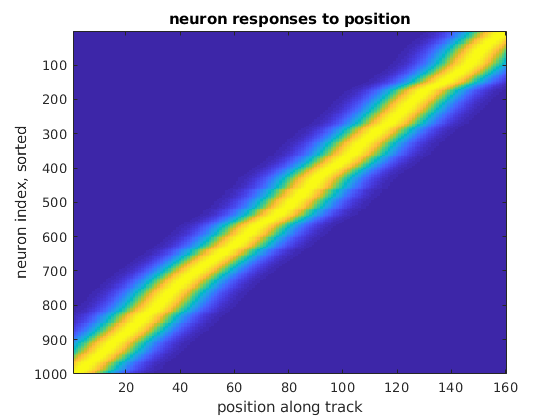

L = 16; N = 1000;
points = linspace(0,L,160);
means = sort(L*rand(N,1), 'descend');
stds = ones(N,1);
base_lambda = 0.05;
Lambdas = @(point) base_lambda .* ...
    (exp(-(point - means).^2./(2*stds)));


responses = Lambdas(points);
figure;
imagesc(responses);
xlabel('position along track');
ylabel('neuron index, sorted');
title('neuron responses to position');

## Trajectory:

Trajectory is back and forth motion along track, ~160 times

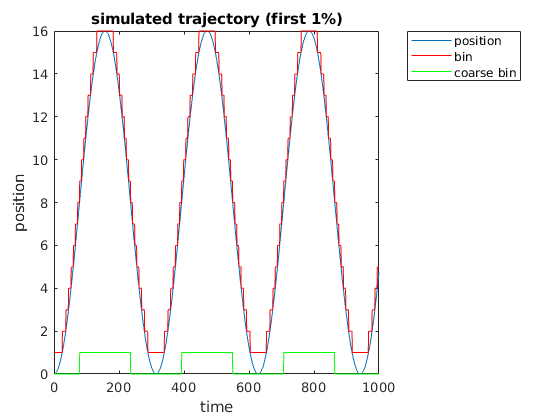

times = 1:100000; speed = 0.01;
trajectory = L*sin(speed*times).^2;
ks = ceil(trajectory);
ks_coarse = trajectory > 8;
figure;
plot(times(1:1000), trajectory(1:1000));
hold on;
plot(times(1:1000), ks(1:1000), 'r');
plot(times(1:1000), ks_coarse(1:1000), 'g');
legend position bin 'coarse bin' Location bestoutside
xlabel('time');
ylabel('position');
title('simulated trajectory (first 1%)');

## Simulated neural responses:

Based on the position from each trajectory, and based on the firing rate of each neuron as a function of position, construct the response patterns

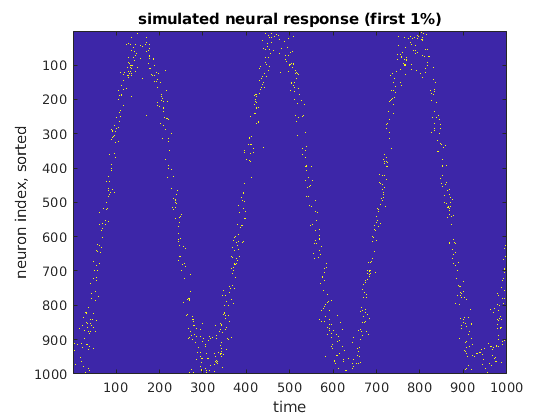

rates = Lambdas(trajectory);
X = double(sparse(rand(size(rates)) < rates))';
figure;
imagesc(X(1:1000,:)');
xlabel('time');
ylabel('neuron index, sorted');
title('simulated neural response (first 1%)');

## Decoding error:

Use misclassification rate as the error of the decoder, rather than mean distance

errf = @(k,p) mean(k(:)~=p(:));

Now run naive Bayes and linear SVM ensembles

algs = my_algs({'mvnb2', 'ecoclin_onevsall'}, {'original', 'shuf'});
par_loops = 4;
train_frac = 0.7;
for i = 1:numel(algs)
    [train_err{1,i}, test_err{1,i}] = evaluate_alg(algs(i),...
        X, ks, 'eval_f', errf,...
        'train_frac', train_frac, 'par_loops', par_loops);
    [train_err{2,i}, test_err{2,i}] = evaluate_alg(algs(i),...
        X, ks_coarse, 'eval_f', errf,...
        'train_frac', train_frac, 'par_loops', par_loops);
end

0.376000 s:running alg Bernoulli NB, with subset? 0


0.172911 s:running alg Bernoulli NB, with subset? 0


0.626394 s:running alg Bernoulli NB (shuf), with subset? 0


0.391463 s:running alg Bernoulli NB (shuf), with subset? 0


27.859714 s:running alg ECOC SVM (1 vs. all), with subset? 0


1.331654 s:running alg ECOC SVM (1 vs. all), with subset? 0


35.036398 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


1.058905 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


Displaying the results:

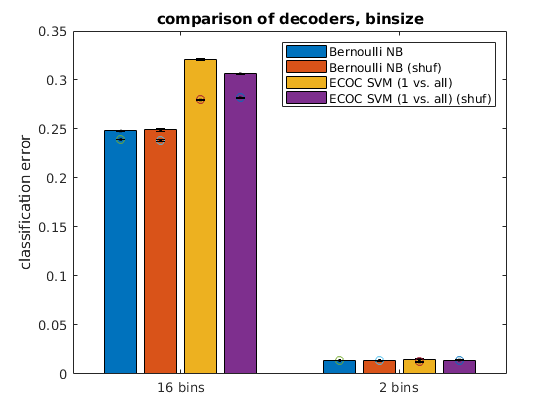

berr({'16 bins', '2 bins'}, test_err, train_err, {algs.name});
ylabel('classification error');
title('comparison of decoders, binsize');